# Sea ice classification

We use CICE6 data to objectively classify a number of distinct sea ice regions using an unsupervised method. The benefit of unsupervised classification is that no definition is imposed and clusters are formed through the distribution of the data in *n*-dimensional space. 

## Set up

clear all
clc
close all

addpath functions
addpath /Users/noahday/GitHub/CICE-analyser/processing

historydir = '/Volumes/NoahDay5TB/WIM_on/history/fullyears/';

a = dir([historydir '/*.nc']);
n_files = numel(a);

for i = 1:n_files
   filenames(i,:) = strcat(historydir,a(i).name);
   dirdates(i,:) = a(i).name(6:end-3);
end

var_list = {'aice','hi','hs','fsdrad','sice','iage','vlvl','vrdg'};
    % Static: {'aice','hi','hs','fsdrad','sice','iage','vlvl','vrdg'}
    % Dynamics: {'aice','hi','hs','fsdrad','sice','iage','vlvl','vrdg', 
    %            'uvel','vvel','strength','divu','shear','daidtd','daidtt',
    %            'dagedtd','dagedtt','dafsd_latg','dafsd_latm','dafsd_newi',
    %            'dafsd_weld','dafsd_wave'};
label_vec = variable_dict(var_list);


## Distribution of each variable

clear Xnan_temp 
load('data/cover_5percent_2015-19.mat')
SIC = 0.15;
[~,wid,dep] = size(data.Xunstandard);
X_temp = data.Xunstandard;%X_raw;
    
for i = 1:dep
    ice_mask = X_temp(:,1,i) > SIC;
    % Step 1: Apply ice mask
    for j = 1:wid
        X_temp(~ice_mask,j,i) = NaN;
    end 
end
idx = [];
Xnan = [];
row_idx = [];
for i = 1:dep
    idxtemp = isnan(X_temp(:,1,i));
    for k = 1:length(idxtemp(:,1))
        idx(k) = prod(~idxtemp(k,:));
    end
    idx = logical(idx);
    for j = 1:wid
        Xnan_temp(:,j) = X_temp(idx',j,i);
    end
    Xnan = [Xnan; Xnan_temp];
    [row, ~] = size(Xnan_temp);
    row_idx(i) = row;
    clear Xnan_temp row
end

[Xnan,row_idx] = clearNaN(X_temp);
disp('Clear NaN done!')

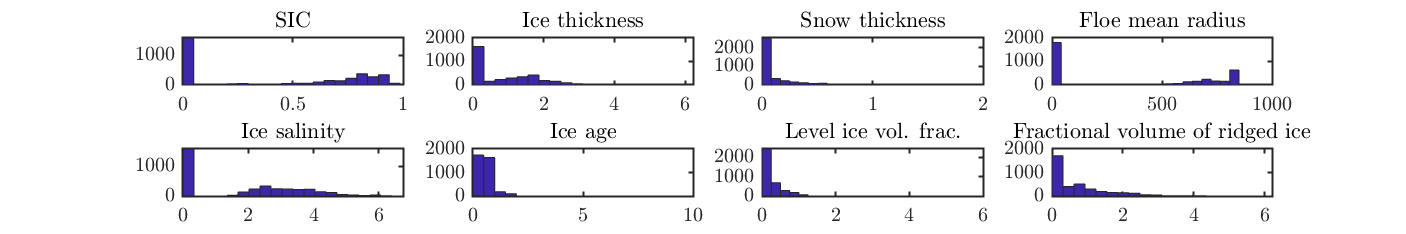


clear Xtemp
close all
conFigure(12,10)
f = figure('Position',[0, 0, 60, 10]);
for i = 1:length(label_vec)
  subplot(2,ceil(length(label_vec)/2),i)
  Xtemp(:,i) = Xnan(idx,i);
  hist(Xtemp(:,i),20)
  %hist(Xnan(idx,i),20)
  %xticks(1:length(average_stats(:,i)))
  title(label_vec{i})
end
exportgraphics(f,'figures/distributionVariables.pdf','ContentType','vector')

## Optimal number of clusters

X_standard_all = Xnan;
[~,wid] = size(X_standard_all);

for j = 1:wid-2 % Don't standardise latitude and longitude
    if min(X_standard_all(:,j)) < 0
        % If negatives, then recentre so its all positive
        max_X(j) = max(X_standard_all(:,j));
        min_X(j) = min(X_standard_all(:,j));
        X_standard_all(:,j) = (X_standard_all(:,j) - min_X(j))/(max_X(j) - min_X(j));
    end
    %Step 1: Log transformation as almost all of the data is highly skewed
        X_standard_all(:,j) = log(X_standard_all(:,j)+1);
    %Step 2: Standardization
    % Calculate mean
        mean_X(j) = mean(X_standard_all(:,j));
        % Calculate standard deviation
        std_X(j) = std(X_standard_all(:,j));
        X_standard_all(:,j) = X_standard_all(:,j)/std_X(j);
    % Standardise the data
        max_X(j) = max(X_standard_all(:,j));
        min_X(j) = min(X_standard_all(:,j));
        X_standard_all(:,j) = (X_standard_all(:,j) - min_X(j))/(max_X(j) - min_X(j));
end
disp('Standardisation done!')

Standardisation done!


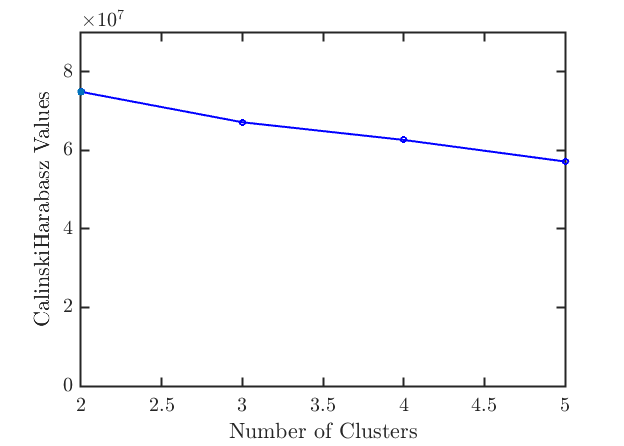


% Plotting
eva = evalclusters(X_standard_all(:,1:end-2),'kmeans','CalinskiHarabasz','KList',1:5);
temp = eva.CriterionValues;
conFigure(11)
f = figure;
plot(eva)
ylim([0,1.2*max(eva.CriterionValues)])
exportgraphics(f,'calinskiHarabasz_cover.pdf','ContentType','vector')

%% Average stats
%Xnan = Xnan(aice_idx,:);
average_stats = [];
X_temp = [];
X_temp = Xnan;
X_temp = [X_temp, kmeans_idx]; % _without_floe

Unrecognized function or variable 'kmeans_idx'.


%X_temp = [X_temp2(:,[1:3 5:end-2]), kmeans_idx];
clear X_temp2
ylabs = {"SIC [\%]", "Ice thickness [m]", "Snow thickness [m]", "Mean floe size [m]",  "Bulk ice salinity [ppt]", "Ice age [years]", "Level ice volume", "Ridged ice volume"};

%"Mean floe radius [m]",
for i = 1:num_clusters
    index_class_data = X_temp(:,end) == i;
    class_data = X_temp(index_class_data,1:end-1);
    average_stats(i,:) = mean(class_data);
end


%%
close all
conFigure(11)
f = figure('Position',[0, 0,40, 6]);% 6, 24]);
label_vec_temp = label_vec;
%label_vec = label_vec([1:3 5:end]);
var_idx = [1,6,2,3,4];%[1,2,5];%

for i = 1:length(var_idx) %1:length(label_vec) % 
  %subplot(2,ceil(length(label_vec(var_idx))/2),i)
  subplot(1,length(var_idx),i)
  if i == 1
    b = bar(average_stats(:,var_idx(i)).*100, 'facecolor', 'flat');
    b.CData = Cmap;
  else
      b = bar(average_stats(:,var_idx(i)), 'facecolor', 'flat');
      b.CData = Cmap;
  end
  xticks(1:length(average_stats(:,i)))
  %title(label_vec{i})
  ylabel(ylabs(var_idx(i)),'FontSize',14)% ylabs
  %xlabel('Sea ice class','FontSize',14)
  if var_idx(i) == 6
      ylim([0,1])
  elseif var_idx(i) == 3
      ylim([0,0.5])
  elseif var_idx(i) == 4
      ylim([0,850])
  end
end
%sgtitle("\textbf{without floe size}",'FontSize',15)
exportgraphics(f,strcat('stat_comparison_',sprintf('%g',num_clusters),'_with_fsd_cover_15_percent_clusters.pdf'),'ContentType','vector')
label_vec = label_vec_temp;

%% Spider plot
% Initialize data points
P = average_stats(:,1:8);
%{'SIC','Ice thick.','Snow thick.','FSD','Salinity'}
% Spider plot
close all
figure
spider_plot(P,...
    'AxesLabels', label_vec,...
    'AxesInterval', 2,...
    'FillOption', {'on', 'on','on','on'},...
    'FillTransparency', 0.2*ones(1,num_clusters),...
    'AxesLimits', [zeros(1,8);1,3,1,850,15,1,1,2]);



%% Comparison of MIZ with and without floe size
ylabs = {"SIC [\%]", "Ice thickness [m]", "Snow thickness [m]", "Mean floe size [m]",  "Bulk ice salinity [ppt]", "Ice age [years]", "Level ice volume", "Ridged ice volume"};

% With floe size
average_stats = [];
X_temp = [];
X_temp = Xnan;
X_temp = [X_temp, kmeans_idx]; 
index_class_data = X_temp(:,end) == 3;
class_data = X_temp(index_class_data,1:end-1);
average_stats(1,:) = mean(class_data);
clear Xtemp class_data

% Without floe size
X_temp = [];
X_temp = Xnan;
X_temp = [X_temp, kmeans_idx_without_floe]; 
index_class_data = X_temp(:,end) == 3;
class_data = X_temp(index_class_data,1:end-1);
average_stats(2,:) = mean(class_data);
clear Xtemp

%
Cmap_comp = [Cmap(3,:); [141,211,199]./258];
close all
conFigure(11)
f = figure('Position',[0, 0,40, 6]);% 6, 24]);
label_vec_temp = label_vec;
%label_vec = label_vec([1:3 5:end]);
var_idx = [1,6,2,3,4];%[1,2,5];%

for i = 1:length(var_idx) %1:length(label_vec) % 
  %subplot(2,ceil(length(label_vec(var_idx))/2),i)
  subplot(1,length(var_idx),i)
  if i == 1
    b = bar(average_stats(:,var_idx(i)).*100, 'facecolor', 'flat');
    b.CData = Cmap_comp;
  else
      b = bar(average_stats(:,var_idx(i)), 'facecolor', 'flat');
      b.CData = Cmap_comp;
  end
  xticks(1:length(average_stats(:,i)))
  %title(label_vec{i})
  ylabel(ylabs(var_idx(i)),'FontSize',14)% ylabs
  %xlabel('Sea ice class','FontSize',14)
  if var_idx(i) == 6
      ylim([0,1])
  elseif var_idx(i) == 3
      ylim([0,0.5])
  elseif var_idx(i) == 4
      ylim([0,850])
  elseif var_idx(i) == 1
      ylim([0,100])
  elseif var_idx(i) == 2
      ylim([0,1])
  end
  xticklabels(["" ""])
  
end
%sgtitle("\textbf{without floe size}",'FontSize',15)
exportgraphics(f,strcat('FSD_comparison_',sprintf('%g',num_clusters),'_cover_15_percent_clusters.pdf'),'ContentType','vector')
label_vec = label_vec_temp;



## Distribution (histogram) plots

%% Distributions between classifications
count = 1;
nBins = 11;
close all
f = figure('Position',[0, 0, 10, 10]);
for j = [1,4]
     % With floe size

    X_temp = [];
    X_temp = Xnan;
    average_stats = [];
    binEdges = linspace(min(X_temp(:,j)),max(X_temp(:,j)),nBins+1);
   
    X_temp = [X_temp, kmeans_idx];
    
    index_class_data = X_temp(:,end) == 3;
    class_data = X_temp(index_class_data,1:end-1);
    average_stats(1,:) = histcounts(class_data(:,j),binEdges,'Normalization','probability');

    % Without floe size
    X_temp = [];
    X_temp = Xnan;
    X_temp = [X_temp, kmeans_idx_without_floe];
    index_class_data = X_temp(:,end) == 3;
    class_data = X_temp(index_class_data,1:end-1);
    average_stats(2,:) = histcounts(class_data(:,j),binEdges,'Normalization','probability');

    subplot(2,1,count)
    for i = 1:2
      Xtemp(:,i) = Xnan(idx,i);
      histogram('BinEdges',binEdges,'BinCounts',average_stats(i,:),'FaceAlpha',.7,'FaceColor',Cmap_comp(i,:))
      grid on
      hold on
      %hist(Xnan(idx,i),20)
      %xticks(1:length(average_stats(:,i)))
      %title(label_vec{j})
      label_hist(i,:) = num2str(i);
      
    end
    ylabel('Probability')
    ylim([0,1])
    xlabel(ylabs{j})
    %legend(label_hist,'Location','bestoutside')
    count = count + 1;
end
exportgraphics(f,'MIZcompdistribution.pdf','ContentType','vector')
%%
line_widths = 40;
close all
f = figure('Position',[0, 0, 60, 10]);
plot(1:5,1:5,'color',Cmap_comp(1,:),'linewidth',line_widths)
hold on
plot(1:5,1:5,'color',Cmap_comp(2,:),'linewidth',line_widths)
legend("MIZ with floe size","MIZ without floe size",'Location','bestoutside','Orientation','vertical','FontSize',20)
exportgraphics(f,strcat('legend_MIZ.pdf'),'ContentType','vector')

%% Distribution of each class

close all

X_temp = [];
[~,~,dep] = size(Xnan);
X_temp = Xnan;
X_temp = [X_temp(:,1:end-2), kmeans_idx];
nBins = 10;
C1 = linspecer(num_clusters);
%Cmap = C1([3,2,1],:);
Cmap = C1([3,2,1],:);
conFigure(12,3)
clear label_hist
f = figure%('Position',[0, 0, 30, 10]);
count = 1;
for j = [1,4]
    average_stats = [];
    binEdges = linspace(min(X_temp(:,j)),max(X_temp(:,j)),nBins+1);
    for i = 1:num_clusters
        index_class_data = X_temp(:,end) == i;
        class_data = X_temp(index_class_data,1:end-1);
        average_stats(i,:) = histcounts(class_data(:,j),binEdges,'Normalization','probability');
    end
    %subplot(2,ceil(length(label_vec)/2),j)
    subplot(1,2,count)
    for i = num_clusters:-1:1
      Xtemp(:,i) = Xnan(idx,i);
      histogram('BinEdges',binEdges,'BinCounts',average_stats(i,:),'FaceAlpha',.7,'FaceColor',Cmap(i,:))
      hold on
      %hist(Xnan(idx,i),20)
      %xticks(1:length(average_stats(:,i)))
      %title(label_vec{j})
      label_hist(i,:) = num2str(i);
      
    end
    ylabel('Probability')
    ylim([0,1])
    xlabel(ylabs{j})
    %legend(label_hist,'Location','bestoutside')
    count = count + 1;
end

exportgraphics(f,'distributionClassVariables.pdf','ContentType','vector')




## Maps

close all
SIC = 0.15;
pram.ice_edge_color = 0.7*[0.4660 0.6740 0.1880];
line_width = 1;

addpath functions
[lat,lon,~,ulat,ulon] = grid_read('om2');
clear X_map MIZ_width
% Make worldmap with colour matching
hdd = "on";

if hdd == "on"
    uarea = data_format(filenames(1,:),"uarea");
end

[num_files,~] = size(filenames);
sector = "SH";
coords = sector_coords(sector);
font_size = 7;
plot_type = "kmeans";
plotting = "on";
conFigure(11)
X_new = Xnan;

[len,wid] = size(lat);
file_number = 1705;%1705%1826;%1705;%366;%609;



row_file = [0,cumsum(row_idx)];
row_vec = row_file(file_number)+1:row_file(file_number+1);
%temp_idx = kmeans_idx_without_floe;
temp_idx = kmeans_idx;
file_idx = temp_idx(row_vec);
file_idx = reshape(file_idx,length(file_idx),1);
if hdd == "on"
    [aice, sector_mask] = data_format_sector(filenames(file_number,:),'aice',sector);
end
X_map = [file_idx, X_new(row_vec,end-1:end)];
k_means = NaN.*ones(len,wid);
for i = 1:length(file_idx)
    [lon_pos,lat_pos,~] = near2(lon,lat,X_map(i,3),X_map(i,2));
    k_means(lon_pos,lat_pos) = file_idx(i); 
    k_means(~sector_mask) = NaN;
end
if hdd == "on"
    ice_mask =  aice > 0.15;
     [lat_ice_edge, lon_ice_edge, edge] = find_ice_edge(aice,0.15,sector,lat,lon);
end
if plotting == "on"
    f = figure;
    set(gcf,'Visible', 'on')
    w = worldmap('world');
        axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
        setm(w, 'Origin', [-90 0 0]);
        setm(w, 'maplatlimit', [-90,-53]);
        setm(w, 'grid', 'off');
        setm(w, 'frame', 'off');
        %setm(w, 'MLineLimit',[-60,-75]);
        %setm(w,'MLineException',[-90 0 90 180])
        setm(w, "FontColor",[0.5, 0.5, 0.5])
        setm(w, 'labelrotation', 'on')
        setm(w, 'meridianlabel', 'on','FontSize',font_size)
        setm(w, 'parallellabel', 'off','FontSize',font_size)
        setm(w, 'mlabellocation', 60);
        setm(w, 'plabellocation', 5);
        pcolorm(lat,lon,k_means,'FaceAlpha',0.99)
        land = shaperead('landareas', 'UseGeoCoords', true);
        geoshow(w, land, 'FaceColor', [0.5 0.5 0.5],'FaceAlpha',.5)
        %colorbar; %cmocean('deep');
        %colormap(Cmap)
        cb = colorbar;
        title(dirdates(file_number,:),'Color','black','FontSize',font_size+3)
        %plotm(lat_ice_edge(1:end-2),lon_ice_edge(1:end-2),'color','#7A7A7A','LineWidth',0.5,'LineStyle','-')
        %textm(lat_ice_edge(190)+2, lon_ice_edge(190),'15\% ice edge', 'FontSize', font_size, 'Color','#7A7A7A')
        scalebar('length',1000,...
            'units','km',...
            'color','k','location','sw',...
            'fontangle','italic','FontSize',font_size)
        if plot_type == "pc1"
            caxis([0,1])
        elseif plot_type == "kmeans"
            %cb = colorbar; cmocean('deep',num_clusters)
            %cb.TickLabels = region_label; 
            cb.Ticks = 1:num_clusters;
            %cb.Location = 'southoutside';%cb.Location = 'northoutside';
            cb.Location = 'eastoutside';
            caxis([0.5,num_clusters+0.5])
            cb.AxisLocation = 'out';
            cb.FontSize = font_size+3;
        end
end

exportgraphics(f,'3cluster.pdf','ContentType','vector')
clear X_map X_temp sb




## Movies


%% MOVIES
clear area_region MIZ_width
SIC = 0.15;
pram.ice_edge_color = 0.7*[0.4660 0.6740 0.1880];
line_width = 1;

addpath functions
[lat,lon,~,ulat,ulon] = grid_read('om2');
clear X_map MIZ_width
% Make worldmap with colour matching
uarea = data_format(filenames(1,:),"uarea");

[num_files,~] = size(filenames);
sector = "SH";
coords = sector_coords(sector);
font_size = 5;
plot_type = "kmeans";
plotting = "off";
conFigure(11)
X_new = Xnan(:,:);
[len,wid] = size(lat);


file_number_vec = 1826-365:10:1826 ;
for file_number = file_number_vec 
    row_file = [0,cumsum(row_idx)];
    row_vec = row_file(file_number)+1:row_file(file_number+1);
    temp_idx = kmeans_idx;
    file_idx = temp_idx(row_vec);
    file_idx = reshape(file_idx,length(file_idx),1);

    [aice, sector_mask] = data_format_sector(filenames(file_number,:),'aice',sector);
    %[lat_ice_edge, lon_ice_edge, edge] = find_ice_edge(aice,SIC,sector,lat,lon);
    X_map = [file_idx, X_new(row_vec,end-1:end)];%[file_idx, X_new(:,end-1:end)];%
    k_means = NaN.*ones(len,wid);
    for i = 1:length(file_idx)
        [lon_pos,lat_pos,~] = near2(lon,lat,X_map(i,3),X_map(i,2));
        k_means(lon_pos,lat_pos) = file_idx(i); 
        k_means(~sector_mask) = NaN;
    end
    
    ice_mask =  aice > 0.15;
   % k_means(~ice_mask) = NaN;
    if plotting == "on"
        f = figure;
        set(gcf,'Visible', 'off')
        w = worldmap('world');
            %axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            %setm(w, 'Origin', [-90 0 0]);
            %setm(w, 'maplatlimit', [-90,-50]);
            
            %setm(w, 'maplonlimit', [coords(1,2),coords(3,2)]);
            if sector == "EA"
                axesm eqdcylin; 
                setm(w, 'Origin', [0 28 0]); 
                setm(w, 'maplatlimit', [-75,-50]); setm(w, 'maplonlimit', [1,150]); 
                setm(w, 'meridianlabel', 'on'); setm(w, 'parallellabel', 'on'); 
                setm(w, 'mlabellocation', 30); setm(w, 'plabellocation', 10); 
                setm(w, 'mlabelparallel', 'south','FontColor','black','FontSize',3);
                setm(w, 'grid', 'off');
                setm(w, 'labelrotation', 'on')
            else
                axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
                setm(w, 'Origin', [-90 0 0]);
                setm(w, 'maplatlimit', [-90,-50]);
                setm(w, 'grid', 'off');
                setm(w, 'labelrotation', 'on')
            end
            pcolorm(lat,lon,k_means)
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.5 0.5])
            %colorbar; %cmocean('deep');
            colormap(Cmap)
            cb = colorbar;
            title(dirdates(file_number,:),'Color','black','FontSize',font_size+5)
            %plotm(lat_ice_edge,lon_ice_edge,'-','color',pram.ice_edge_color,'LineWidth',line_width)

            %cb = colorbar; cmocean('deep',num_clusters)
            %cb.TickLabels = region_label; 
            cb.Ticks = 1:num_clusters;
            %cb.Location = 'southoutside';%cb.Location = 'northoutside';
            cb.Location = 'eastoutside';
            caxis([1,num_clusters])
            cb.AxisLocation = 'in';

    end
    % Calculate the width of the MIZ
    % CHECK WHAT number MIZ is !!!!!!!!
    [MIZ_width(file_number,:), miz_class, MIZ_zone] = calculate_miz_width(convertStringsToChars(filenames(file_number,:)),sector,k_means,3);
    

    % Calculate the perimeter and area of the zones
    for rgn_number = 1:num_clusters
        region_data = k_means == rgn_number;
        [len, wid] = size(k_means);
        perimeter_region(rgn_number,file_number) = find_perimeter(region_data,len,wid);

        % Area
        area_region(rgn_number, file_number) = sum(sum(uarea.*region_data));
    end
    if plotting == "on"
        if file_number == file_number_vec(1)
            gif('kmeans_SH_SA_05_stndzd_3class2014.gif','DelayTime',0.5,'resolution',500,'overwrite',true)
        else
            gif
        end
    end
    k_means_map(:,:,file_number) = k_means;
    % Clear the excess
    clear aice ice_mask k_means file_idx X_map
end